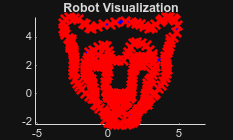

%% EXAMPLE: Differential drive vehicle following waypoints using the
% Pure Pursuit algorithm
%
% Copyright 2018-2019 The MathWorks, Inc.

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Waypoints
waypoints = [
    -0.0905,2.1132; -0.1250,2.3690; -0.3532,2.6387; -0.6644,2.7148;
    -1.1139,2.6733; -1.3628,2.5834; -1.2936,2.9360; -1.0378,3.0951;
    -0.6575,3.2956; -0.3186,3.4270; -0.1112,3.3648; 0.0000,3.0000;
    0.0686,2.7424; 0.1931,2.4451; 0.4213,2.3828; 0.7117,2.3621;
    1.0713,2.3759; 1.3479,2.6318; 1.4585,2.8876; 1.5968,3.2610;
    1.7697,3.5930; 2.0324,3.6344; 2.3367,3.5722; 2.6963,3.3993;
    2.9175,3.0882; 3.1457,2.8047; 3.1596,2.5626; 3.0000,2.5000;
    2.8069,2.5972; 2.5026,2.6110; 2.3021,2.5972; 2.1776,2.6041;
    2.0000,2.5000; 1.9356,2.3690; 1.9564,2.1547; 2.1085,2.0648;
    2.3090,2.0233; 2.5000,2.0000; 2.6963,2.1547; 2.8207,2.3898;
    3.1872,2.2653; 3.3117,1.9403; 3.2356,1.6360; 3.1250,1.4009;
    3.0420,1.0967; 2.8968,0.9376; 2.7931,0.7578; 2.7447,0.5573;
    2.7447,0.2807; 2.7064,0.0498; 2.6616,-0.1474; 2.6257,-0.4163;
    2.6526,-0.5597; 2.5899,-0.7569; 2.4411,-0.9106; 2.3486,-1.0031;
    2.1702,-1.0891; 2.0710,-1.2741; 1.9785,-1.4063; 1.9653,-1.6178;
    1.9587,-1.7830; 1.8133,-1.9615; 1.6943,-2.0408; 1.5159,-2.0936;
    1.2647,-2.1663; 0.9739,-2.1928; 0.7161,-2.1663; 0.4121,-2.1399;
    0.2072,-2.0936; 0.0000,-2.0000; -0.1563,-1.7896; -0.1695,-1.4658;
    -0.1959,-1.3270; -0.2951,-1.1750; -0.5793,-1.0560; -0.7511,-0.8379;
    -0.8701,-0.7322; -0.9626,-0.3554; -0.9428,-0.1175; -0.9626,0.1336;
    -1.0348,0.3568; -1.1512,0.4807; -1.1174,0.6647; -1.1850,0.8261;
    -1.2000,1.0000; -1.3239,1.0927; -1.4000,1.2000; -1.4966,1.3669;
    -1.5667,1.5046; -1.5944,1.6916; -1.6291,1.8683; -1.6083,2.1316;
    -1.4680,2.3287; -1.3752,2.4966; -1.2739,2.2803; -1.1912,2.1491;
    -1.0357,2.0665; -0.9094,2.0082; -0.7150,1.9547; -0.4623,1.9159;
    -0.2922,1.9596; -0.0832,1.9839; -0.0687,1.7360; -0.0103,1.5514;
    -0.0735,1.2792; -0.1221,1.0751; -0.1853,0.8273; -0.1981,0.5964;
    -0.1083,0.2501; 0.0000,0.0000; 0.3791,0.0192; 0.6187,-0.0238;
    0.8316,-0.0676; 1.1008,-0.0363; 1.3138,0.0013; 1.5000,0.0000;
    1.5768,-0.0551; 1.6582,-0.2054; 1.4954,-0.3494; 1.3388,-0.5623;
    1.2261,-0.6688; 1.0758,-0.8316; 0.8817,-0.9819; 0.6437,-0.8504;
    0.5435,-0.7439; 0.4558,-0.6312; 0.3118,-0.4872; 0.2241,-0.3306;
    0.0551,-0.2367; -0.0577,-0.1052; -0.1140,0.1391; 0.2116,0.0514;
    1.0006,-0.0676; 1.6269,0.1954; 1.6394,0.3770; 1.6644,0.5837;
    1.7145,0.8843; 1.7145,1.1535; 1.7458,1.3351; 1.7897,1.6482;
    1.8305,1.7962; 1.8653,1.9912; 1.9303,2.1281; 2.0788,2.0098;
    2.3156,1.9866; 2.9402,2.3339; 4.0220,2.4513; 4.0691,2.6610;
    4.1632,2.8920; 4.2745,3.1188; 4.3472,3.3328; 4.4000,3.6000;
    4.3745,3.8068; 4.6346,3.9716; 4.7907,4.3271; 4.8947,4.8039;
    4.7647,5.1681; 4.5957,5.3532; 4.3181,5.4110; 4.0869,5.3648;
    3.8209,5.2607; 3.6706,5.0873; 3.3468,4.8791; 3.1387,4.6825;
    2.9074,4.6247; 2.5721,4.7519; 2.2945,4.8907; 2.0000,5.0000;
    1.6701,5.0295; 1.2192,5.0988; 0.5138,5.0526; 0.1553,4.9254;
    -0.2957,4.8676; -0.7235,4.7404; -1.1513,4.6132; -1.3479,4.6594;
    -1.5676,4.8676; -1.7180,4.9832; -2.0764,5.2492; -2.3771,5.3532;
    -2.7124,5.4110; -2.9784,5.2376; -3.1287,4.9369; -3.1403,4.6363;
    -3.1063,4.4107; -3.0109,4.1781; -2.8319,3.9157; -2.5993,3.8680;
    -2.5874,3.7189; -2.6411,3.5817; -2.6649,3.4505; -2.6828,3.2954;
    -2.5397,3.1761; -2.4204,3.0330; -2.4323,2.9256; -2.4261,2.7577;
    -2.3660,2.5351; -2.3720,2.3246; -2.3539,2.1202; -2.4201,1.9097;
    -2.4321,1.6330; -2.4201,1.3624; -2.3299,0.9956; -2.1615,0.7189;
    -2.0000,0.5000; -1.8613,0.2847; -1.5712,0.0175; -1.2963,-0.1810;
    -1.1284,-0.3261; 0.0000,-1.5000; 0.3004,-1.4632; 0.6379,-1.3571;
    0.9560,-1.2800; 1.3610,-1.4439; 1.7852,-1.5500; 2.7687,-0.7401;
    2.8063,-0.5038; 2.8399,-0.3787; 2.9955,-0.2719; 3.1816,-0.1102;
    3.3220,0.0637; 3.5354,0.3661; 3.7666,0.6151; 3.9266,0.8818;
    4.0423,1.1397; 4.1490,1.4687; 4.1720,1.6880; 4.1170,1.9108;
    4.0861,2.0929; 4.0247,2.2990
];

%% Simulation parameters
sampleTime = 0.1;                                   % Sample time [s]
initPose = [waypoints(1,1); waypoints(1,2); 0];     % Arranca en el primer waypoint

% Tiempo dinámico segun longitud del path
pathLen = sum(vecnorm(diff(waypoints), 2, 2));
desiredV = 1.0;
tEnd = 1.02* pathLen / desiredV;                    % 50% margen
tVec = 0:sampleTime:tEnd;

pose = zeros(3,numel(tVec));
pose(:,1) = initPose;

% Visualizador
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.25;% bajo para seguir contorno fielmente
controller.DesiredLinearVelocity = desiredV;
controller.MaxAngularVelocity = 5;



%% Simulation loop
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec)
    % Pure Pursuit -> velocidades de rueda
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);

    % Velocidades del cuerpo
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w];
    vel = bodyToWorld(velB,pose(:,idx-1));

    % Integración discreta
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime;

    % Visualización
    viz(pose(:,idx),waypoints);
    waitfor(r);
end

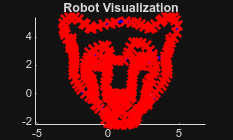

clc; clear; close all

%% 1. TIEMPO
ts = 0.05;
tf = 300;                 % se corta solo al llegar al final
t  = 0:ts:tf;
N  = length(t);

%% 2. WAYPOINTS 
waypoints = [
    -0.0905,2.1132; -0.1250,2.3690; -0.3532,2.6387; -0.6644,2.7148;
    -1.1139,2.6733; -1.3628,2.5834; -1.2936,2.9360; -1.0378,3.0951;
    -0.6575,3.2956; -0.3186,3.4270; -0.1112,3.3648; 0.0000,3.0000;
    0.0686,2.7424; 0.1931,2.4451; 0.4213,2.3828; 0.7117,2.3621;
    1.0713,2.3759; 1.3479,2.6318; 1.4585,2.8876; 1.5968,3.2610;
    1.7697,3.5930; 2.0324,3.6344; 2.3367,3.5722; 2.6963,3.3993;
    2.9175,3.0882; 3.1457,2.8047; 3.1596,2.5626; 3.0000,2.5000;
    2.8069,2.5972; 2.5026,2.6110; 2.3021,2.5972; 2.1776,2.6041;
    2.0000,2.5000; 1.9356,2.3690; 1.9564,2.1547; 2.1085,2.0648;
    2.3090,2.0233; 2.5000,2.0000; 2.6963,2.1547; 2.8207,2.3898;
    3.1872,2.2653; 3.3117,1.9403; 3.2356,1.6360; 3.1250,1.4009;
    3.0420,1.0967; 2.8968,0.9376; 2.7931,0.7578; 2.7447,0.5573;
    2.7447,0.2807; 2.7064,0.0498; 2.6616,-0.1474; 2.6257,-0.4163;
    2.6526,-0.5597; 2.5899,-0.7569; 2.4411,-0.9106; 2.3486,-1.0031;
    2.1702,-1.0891; 2.0710,-1.2741; 1.9785,-1.4063; 1.9653,-1.6178;
    1.9587,-1.7830; 1.8133,-1.9615; 1.6943,-2.0408; 1.5159,-2.0936;
    1.2647,-2.1663; 0.9739,-2.1928; 0.7161,-2.1663; 0.4121,-2.1399;
    0.2072,-2.0936; 0.0000,-2.0000; -0.1563,-1.7896; -0.1695,-1.4658;
    -0.1959,-1.3270; -0.2951,-1.1750; -0.5793,-1.0560; -0.7511,-0.8379;
    -0.8701,-0.7322; -0.9626,-0.3554; -0.9428,-0.1175; -0.9626,0.1336;
    -1.0348,0.3568; -1.1512,0.4807; -1.1174,0.6647; -1.1850,0.8261;
    -1.2000,1.0000; -1.3239,1.0927; -1.4000,1.2000; -1.4966,1.3669;
    -1.5667,1.5046; -1.5944,1.6916; -1.6291,1.8683; -1.6083,2.1316;
    -1.4680,2.3287; -1.3752,2.4966; -1.2739,2.2803; -1.1912,2.1491;
    -1.0357,2.0665; -0.9094,2.0082; -0.7150,1.9547; -0.4623,1.9159;
    -0.2922,1.9596; -0.0832,1.9839; -0.0687,1.7360; -0.0103,1.5514;
    -0.0735,1.2792; -0.1221,1.0751; -0.1853,0.8273; -0.1981,0.5964;
    -0.1083,0.2501; 0.0000,0.0000; 0.3791,0.0192; 0.6187,-0.0238;
    0.8316,-0.0676; 1.1008,-0.0363; 1.3138,0.0013; 1.5000,0.0000;
    1.5768,-0.0551; 1.6582,-0.2054; 1.4954,-0.3494; 1.3388,-0.5623;
    1.2261,-0.6688; 1.0758,-0.8316; 0.8817,-0.9819; 0.6437,-0.8504;
    0.5435,-0.7439; 0.4558,-0.6312; 0.3118,-0.4872; 0.2241,-0.3306;
    0.0551,-0.2367; -0.0577,-0.1052; -0.1140,0.1391; 0.2116,0.0514;
    1.0006,-0.0676; 1.6269,0.1954; 1.6394,0.3770; 1.6644,0.5837;
    1.7145,0.8843; 1.7145,1.1535; 1.7458,1.3351; 1.7897,1.6482;
    1.8305,1.7962; 1.8653,1.9912; 1.9303,2.1281; 2.0788,2.0098;
    2.3156,1.9866; 2.9402,2.3339; 4.0220,2.4513; 4.0691,2.6610;
    4.1632,2.8920; 4.2745,3.1188; 4.3472,3.3328; 4.4000,3.6000;
    4.3745,3.8068; 4.6346,3.9716; 4.7907,4.3271; 4.8947,4.8039;
    4.7647,5.1681; 4.5957,5.3532; 4.3181,5.4110; 4.0869,5.3648;
    3.8209,5.2607; 3.6706,5.0873; 3.3468,4.8791; 3.1387,4.6825;
    2.9074,4.6247; 2.5721,4.7519; 2.2945,4.8907; 2.0000,5.0000;
    1.6701,5.0295; 1.2192,5.0988; 0.5138,5.0526; 0.1553,4.9254;
    -0.2957,4.8676; -0.7235,4.7404; -1.1513,4.6132; -1.3479,4.6594;
    -1.5676,4.8676; -1.7180,4.9832; -2.0764,5.2492; -2.3771,5.3532;
    -2.7124,5.4110; -2.9784,5.2376; -3.1287,4.9369; -3.1403,4.6363;
    -3.1063,4.4107; -3.0109,4.1781; -2.8319,3.9157; -2.5993,3.8680;
    -2.5874,3.7189; -2.6411,3.5817; -2.6649,3.4505; -2.6828,3.2954;
    -2.5397,3.1761; -2.4204,3.0330; -2.4323,2.9256; -2.4261,2.7577;
    -2.3660,2.5351; -2.3720,2.3246; -2.3539,2.1202; -2.4201,1.9097;
    -2.4321,1.6330; -2.4201,1.3624; -2.3299,0.9956; -2.1615,0.7189;
    -2.0000,0.5000; -1.8613,0.2847; -1.5712,0.0175; -1.2963,-0.1810;
    -1.1284,-0.3261; 0.0000,-1.5000; 0.3004,-1.4632; 0.6379,-1.3571;
    0.9560,-1.2800; 1.3610,-1.4439; 1.7852,-1.5500; 2.7687,-0.7401;
    2.8063,-0.5038; 2.8399,-0.3787; 2.9955,-0.2719; 3.1816,-0.1102;
    3.3220,0.0637; 3.5354,0.3661; 3.7666,0.6151; 3.9266,0.8818;
    4.0423,1.1397; 4.1490,1.4687; 4.1720,1.6880; 4.1170,1.9108;
    4.0861,2.0929; 4.0247,2.2990
];

tol   = 0.15;             % tolerancia para cambiar de waypoint [m]
numWP = size(waypoints,1);
wpIdx = 1;

%% 3. CONDICIONES INICIALES
% Arranca en el primer waypoint, orientado hacia el segundo
pose = [ waypoints(1,1);
         waypoints(1,2);
         atan2(waypoints(2,2)-waypoints(1,2), waypoints(2,1)-waypoints(1,1)) ];

poseHist = zeros(3, N);
poseHist(:,1) = pose;

%% 4. PARAMETROS CONTROL ADAPTATIVO  
Kv0 = 0.8;   Kw0 = 1.5;
alpha_v = 0.08;  alpha_w = 0.05;
Kv_max = 2.5;  Kw_max = 3.5;
Kv_min = 0.3;  Kw_min = 0.5;
v_max = 1.2;   w_max = 1.5;
v_prev = 0;    w_prev = 0;
beta = 0.85;

%% 5. VISUALIZADOR LIGERO (coche como el de Pure Pursuit)
viz = Visualizer2D;
viz.hasWaypoints = true;
r = rateControl(1/ts);

%% 6. LOGS
v     = zeros(1,N);
w     = zeros(1,N);
Error = zeros(1,N);
wpLog = zeros(1,N);

%% 7. BUCLE DE CONTROL
kEnd = N;
for k = 1:N

    % Waypoint activo
    hxd = waypoints(wpIdx,1);
    hyd = waypoints(wpIdx,2);

    %% ERRORES
    hxe = hxd - pose(1);
    hye = hyd - pose(2);
    Error(k) = hypot(hxe, hye);

    phi_d = atan2(hye, hxe);
    e_phi = atan2(sin(phi_d - pose(3)), cos(phi_d - pose(3)));  % normalizacion

    %% GANANCIAS AUTO-SINTONIZABLES
    Kv = min(max(Kv0 + alpha_v*Error(k),  Kv_min), Kv_max);
    Kw = min(max(Kw0 + alpha_w*abs(e_phi), Kw_min), Kw_max);

    %% CONTROLADOR
    v_raw = Kv * Error(k) * cos(e_phi);   % reduce v si hay error angular
    w_raw = Kw * e_phi;

    %% SATURACION
    v_raw = max(min(v_raw,  v_max), -v_max);
    w_raw = max(min(w_raw,  w_max), -w_max);

    %& FILTRO SUAVIZANTE
    v(k) = beta*v_prev + (1-beta)*v_raw;
    w(k) = beta*w_prev + (1-beta)*w_raw;
    v_prev = v(k);  w_prev = w(k);

    %% CAMBIO DE WAYPOINT
    wpLog(k) = wpIdx;
    if Error(k) <= tol && wpIdx < numWP
        wpIdx = wpIdx + 1;
        v_prev = 0;  w_prev = 0;          % reset filtro para arranque limpio
    end

    %% MODELO CINEMATICO (uniciclo, Euler) 
    xp = v(k)*cos(pose(3));
    yp = v(k)*sin(pose(3));
    pose(1) = pose(1) + xp*ts;
    pose(2) = pose(2) + yp*ts;
    pose(3) = pose(3) + w(k)*ts;

    poseHist(:,k) = pose;

    %% VISUALIZACION
    viz(pose, waypoints);
    waitfor(r);

    %% SALIDA TEMPRANA
    if wpIdx == numWP && Error(k) <= tol
        kEnd = k;
        fprintf('Meta alcanzada en t = %.2f s\n', k*ts);
        break;
    end
end

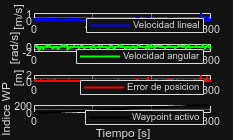


poseHist = poseHist(:,1:kEnd);
v = v(1:kEnd); w = w(1:kEnd); Error = Error(1:kEnd); wpLog = wpLog(1:kEnd);
tk = (0:kEnd-1)*ts;

%% 8. GRAFICAS DE SEÑALES
figure;
subplot(4,1,1); plot(tk, v, 'b', 'LineWidth',1.5); grid on
ylabel('[m/s]'); legend('Velocidad lineal');
subplot(4,1,2); plot(tk, w, 'g', 'LineWidth',1.5); grid on
ylabel('[rad/s]'); legend('Velocidad angular');
subplot(4,1,3); plot(tk, Error, 'r', 'LineWidth',1.5); grid on
ylabel('[m]'); legend('Error de posicion');
subplot(4,1,4); stairs(tk, wpLog, 'k', 'LineWidth',1.5); grid on
xlabel('Tiempo [s]'); ylabel('Indice WP'); legend('Waypoint activo');

**Conclusiones:**

Para obtener el recorrido de las trayectorias se optó por dos estrategias de control en lazo cerrado basadas en waypoints: un controlador **Pure Pursuit** y un controlador** de posición punto a punto**. La razón principal de esta elección fue su facilidad de implementación y su robustez frente a un esquema en lazo abierto. En lazo abierto habría sido necesario calcular manualmente los perfiles de velocidad lineal (*v*) y angular (*w*) para cada tramo del recorrido; esto resulta inviable para una trayectoria de cientos de puntos como la del contorno trazado, y además no corrige errores: cualquier desviación por integración numérica o redondeo se acumula y deforma el resultado final. Al trabajar con waypoints, basta con definir la posición de destino y el control realimentado determina automáticamente *v* y *w* a partir del error de posición y orientación, garantizando la convergencia a cada punto independientemente de pequeñas perturbaciones.

Pure Pursuit se eligió por generar trayectorias suaves y estables siguiendo el camino mediante un punto de anticipación (*lookahead*), lo que evita oscilaciones en las curvas del trazo. El controlador adaptativo de posición se incorporó como método alternativo, ajustando sus ganancias *Kv* y *Kw* en función de la magnitud del error, lo que permite acelerar en tramos largos y suavizar la aproximación al acercarse a cada waypoint.

Adicionalmente, en la segunda estrategia se modificó la simulación para hacerla más eficiente. Se sustituyó el renderizado tridimensional del robot, que recalculaba y redibujaba la malla y la trayectoria completa en cada iteración, con un costo computacional complejo por una visualización 2D ligera (`Visualizer2D`); la trayectoria recorrida se grafica una sola vez al finalizar y se añadió una condición de paro temprano al alcanzar el último waypoint. Estos ajustes redujeron de forma significativa el tiempo de cómputo y eliminaron los bloqueos de la animación que presentaba mi laptop, sin alterar la lógica de control.